%Problem 2.21
clear;
m=sym('m','positive');
hbar = sym('hbar', 'positive');
t=sym('t','positive');
A = sym('A', 'positive');
alpha = sym('alpha', 'positive');
pi=sym('pi','positive');
x = sym('x', 'real');
k = sym('k', 'real');
psi(x)=A*exp(-alpha*x^2)

$$psi(x) = A\,{\mathrm{e}}^{-\alpha \,x^{2}}$$


Asol=solve(int(psi(x)^2,x,-inf,inf)==1,A)

$$Asol = \frac{2^{1/4}\,\alpha^{1/4}}{\pi^{1/4}}$$

psinorm(x)=subs(psi(x),A,Asol)

$$psinorm(x) = \frac{2^{1/4}\,\alpha^{1/4}\,{\mathrm{e}}^{-\alpha \,x^{2}}}{\pi^{1/4}}$$


%b)

phi(k) = 1/sqrt(2*pi)*simplify( int(psinorm(x)*exp(-1i*k*x), x, -inf, +inf) )

$$phi(k) = \frac{2^{3/4}\,\pi^{1/4}\,{\mathrm{e}}^{-\frac{k^{2}}{4\,\alpha }}}{2\,\alpha^{1/4}\,\sqrt{\pi }}$$


integrand=simplify(1/sqrt(2*pi)*phi(k)*exp(1i*k*x)*exp(-1i*hbar*k^2/2/m*t))

$$integrand = \frac{2^{1/4}\,\pi^{1/4}\,{\mathrm{e}}^{-\frac{\mathrm{hbar}\,k^{2}\,t\,\mathrm{i}}{2\,m}}\,{\mathrm{e}}^{-\frac{k^{2}}{4\,\alpha }}\,{\mathrm{e}}^{k\,x\,\mathrm{i}}}{2\,\alpha^{1/4}\,\pi }$$

psit_bad(x,t)=int(1/sqrt(2*pi)*phi(k)*exp(1i*k*x)*exp(-1i*hbar*k^2/2/m*t),k,-inf,inf)

$$psit\_bad(x, t) = \begin{array}{l} -\frac{2^{1/4}\,\pi^{1/4}\,\left(\frac{\sqrt{\alpha }\,\sqrt{m}\,\sqrt{\pi }\,\sigma_{1}\,\left(\lim_{k\to -\infty }\sigma_{2}\right)\,\mathrm{i}}{\sqrt{-m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}-\frac{\sqrt{\alpha }\,\sqrt{m}\,\sqrt{\pi }\,\sigma_{1}\,\left(\lim_{k\to \infty }\sigma_{2}\right)\,\mathrm{i}}{\sqrt{-m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}\right)}{\alpha^{1/4}\,\pi \,2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\alpha \,m^{2}\,x^{2}-2\,\alpha^{2}\,\mathrm{hbar}\,m\,t\,x^{2}\,\mathrm{i}}{4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}\\ \sigma_{2}=\mathrm{erf}\left(\frac{k\,m\,\mathrm{i}+2\,\alpha \,m\,x-k\,\alpha \,\mathrm{hbar}\,t\,2}{\sqrt{\alpha }\,\sqrt{m}\,\sqrt{-m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,2}\right) \end{array}$$


gamma = sym('gamma', 'positive');

integrand_gamma = 1/sqrt(2*pi) * subs(integrand, exp(-k^2/(4*alpha)), exp(-gamma*k^2)/exp(-i*hbar*k^2*t/(2*m)))

$$integrand\_gamma = \frac{2^{3/4}\,\pi^{1/4}\,{\mathrm{e}}^{k\,x\,\mathrm{i}}\,{\mathrm{e}}^{-\gamma \,k^{2}}}{4\,\alpha^{1/4}\,\pi^{3/2}}$$



I_gamma = simplify(int(integrand_gamma, k, -inf, inf))

$$I\_gamma = \frac{2^{3/4}\,\pi^{3/4}\,{\mathrm{e}}^{-\frac{x^{2}}{4\,\gamma }}}{4\,\alpha^{1/4}\,\sqrt{\gamma }\,\pi^{3/2}}$$

psit = simplify(subs(I_gamma, gamma, 1/(4*alpha) + 1i*hbar*t/(2*m)))

$$psit = \frac{2^{3/4}\,\alpha^{1/4}\,\sqrt{m}\,\pi^{3/4}\,{\mathrm{e}}^{-\frac{\alpha \,m\,x^{2}}{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}}{2\,\pi^{3/2}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}$$


%c)

conj(psit)*psit

$$ans = \frac{\sqrt{2}\,\sqrt{\alpha }\,m\,\pi^{3/2}\,{\mathrm{e}}^{-\frac{\alpha \,m\,x^{2}}{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}\,{\mathrm{e}}^{-\frac{\alpha \,m\,x^{2}}{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}}{2\,\pi^{3}\,\sqrt{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}$$

psit2(x,t) = simplify(ans, 'Steps', 100)

$$psit2(x, t) = \frac{\sqrt{2}\,\sqrt{\alpha }\,m\,\pi^{3/2}\,{\mathrm{e}}^{-\frac{2\,\alpha \,m^{2}\,x^{2}}{4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}}{2\,\pi^{3}\,\sqrt{4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}$$

clear pi
x_vals = linspace(-5, 5, 500);
psit2_num2 = subs(psit2(x,t), {alpha, m, hbar, sym('pi')}, {1, 1, 1, pi});
symvar(subs(psit2_num2, {x, t}, {1, 0}))

 
ans =
 
Empty sym: 1-by-0
 


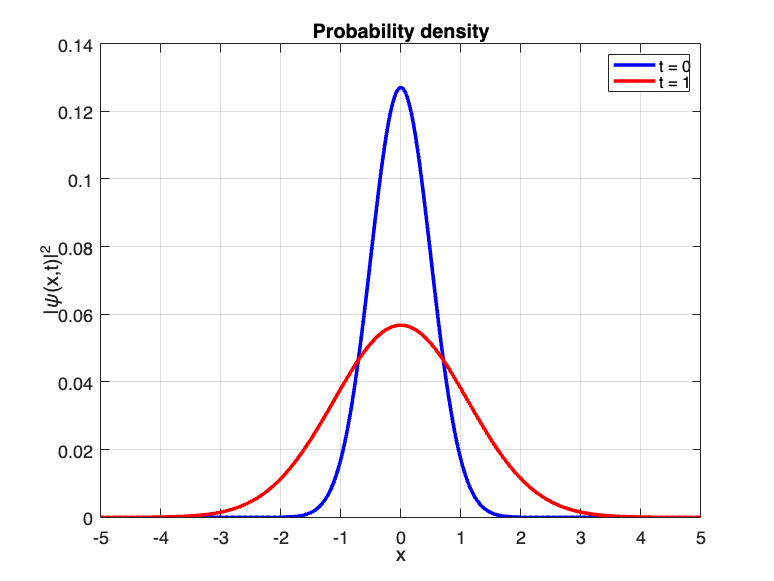


% Now evaluate
y0 = double(subs(psit2_num2, {x, t}, {x_vals, 0}));
y1 = double(subs(psit2_num2, {x, t}, {x_vals, 1}));
% Plot
figure;
plot(x_vals, real(y0), 'b-', 'LineWidth', 2, 'DisplayName', 't = 0');
hold on
plot(x_vals, real(y1), 'r-', 'LineWidth', 2, 'DisplayName', 't = 1');
xlabel('x');
ylabel('|\psi(x,t)|^2');
title('Probability density');
legend;
grid on

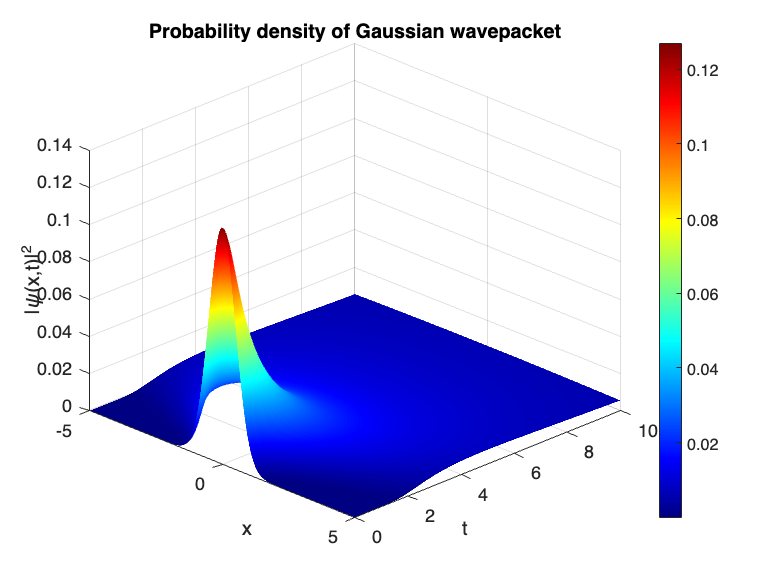

psit2_fun = matlabFunction(psit2_num2, 'Vars', [x, t]);

% Create grid
x_vals = linspace(-5, 5, 200);
t_vals = linspace(0, 10, 200);
[X, T] = meshgrid(x_vals, t_vals);
% Evaluate on grid
Z = real(psit2_fun(X, T));
% 3D surface plot
figure;
surf(X, T, Z, 'EdgeColor', 'none');
xlabel('x');
ylabel('t');
zlabel('|\psi(x,t)|^2');
title('Probability density of Gaussian wavepacket');
colormap(jet);
colorbar;
shading interp;
view(45, 30);


%d)
xavg=simplify(int(conj(psit)*x*psit,x,-inf,inf))

$$xavg = 0$$

x2avg=simplify(int(conj(psit)*x^2*psit,x,-inf,inf))

$$x2avg = \frac{\pi^{2}\,{\left(4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}^{3/2}}{8\,\alpha \,m^{2}\,\pi^{3}\,\sqrt{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}$$

pavg=simplify(int(conj(psit)*(hbar/i)*diff(psit,x),x,-inf,inf))

$$pavg = 0$$

p2avg=simplify(int(conj(psit)*(hbar/i)^2*diff(psit,x,2),x,-inf,inf))

$$p2avg = \frac{\alpha \,{\mathrm{hbar}}^{2}\,\pi^{2}\,\sqrt{4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}{2\,\pi^{3}\,\sqrt{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}$$


stdevx=simplify(sqrt(x2avg-xavg^2))

$$stdevx = \frac{\pi \,\sqrt{2}\,{\left(4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}^{3/4}\,\sqrt{\frac{1}{\sqrt{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}}}{4\,\sqrt{\alpha }\,m\,\pi^{3/2}}$$

stdevp=simplify(sqrt(p2avg-pavg^2))

$$stdevp = \frac{\pi \,\sqrt{2}\,\sqrt{\alpha }\,\mathrm{hbar}\,{\left(4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}\right)}^{1/4}\,\sqrt{\frac{1}{\sqrt{m-2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}\,\sqrt{m+2\,\alpha \,\mathrm{hbar}\,t\,\mathrm{i}}}}}{2\,\pi^{3/2}}$$


heisen(t)=simplify(stdevx*stdevp,'Steps',100)

$$heisen(t) = \frac{\mathrm{hbar}\,\pi^{2}\,\sqrt{4\,\alpha^{2}\,{\mathrm{hbar}}^{2}\,t^{2}+m^{2}}}{4\,m\,\pi^{3}}$$

%Uncertainty product at t=0:
heisenValue = heisen(0);
fprintf('Uncertainty product at t=0: %s\n', char(heisenValue));

Uncertainty product at t=0: (hbar*pi^2)/(4*pi^3)


%Problem 2.27
clear;
syms A B
m=sym('m','positive');
hbar=sym('hbar','positive');
a=sym('a','positive');
al=sym('alpha','positive');
E=sym('E','positive');
x=sym('x','real');
k=sqrt((2*m*E)/hbar^2);
assume(B~=0);

psiR(x)=A*exp(-k*x)

$$psiR(x) = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}$$

psiC(x)=B*(exp(k*x)+exp(-k*x))

$$psiC(x) = B\,\left({\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}+{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}\right)$$

psiL(x)=A*exp(-k*x)

$$psiL(x) = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}$$


dpsiR(x)=diff(psiR(x),x)

$$dpsiR(x) = -\frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}$$

dpsiC(x)=diff(psiC(x),x)

$$dpsiC(x) = B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}\right)$$

dpsiL(x)=diff(psiL(x),x)

$$dpsiL(x) = -\frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}$$


eq1=psiR(a)==psiC(a)

$$eq1 = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}=B\,\left({\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}+{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}\right)$$

eq2=dpsiR(a)-dpsiC(a)==((-2*m*al)/hbar^2)*psiR(a)

$$eq2 = \begin{array}{l} -B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}}{\mathrm{hbar}}-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{\mathrm{hbar}}\right)-\frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{\mathrm{hbar}}=-\frac{2\,A\,\alpha \,m\,\sigma_{1}}{{\mathrm{hbar}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}} \end{array}$$


Asol=simplify(solve(eq1,A))

$$Asol = B\,\left({\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}+1\right)$$

eq2=simplify(subs(eq2,A,Asol),'Steps',100)

$$eq2 = 2\,\alpha \,m\,\cosh\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}\right)=\sqrt{2}\,\sqrt{\text{E}}\,\mathrm{hbar}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}$$

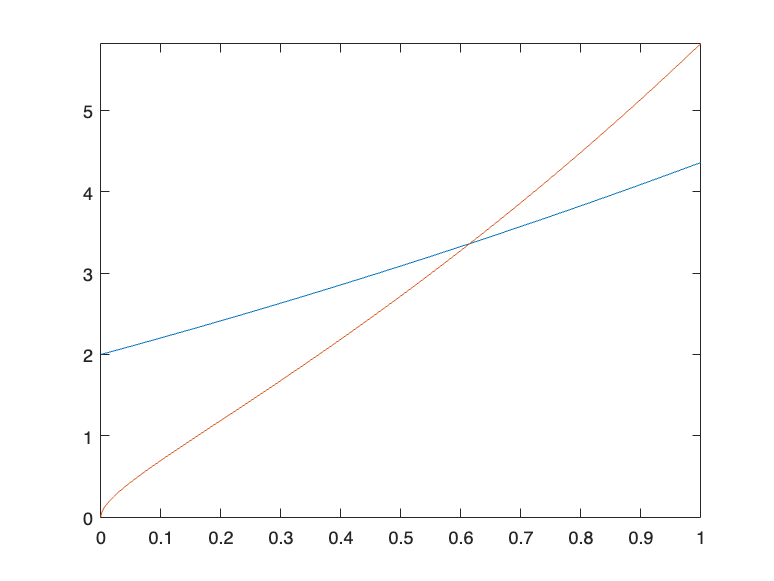


eq2plotA1(E)=simplify(subs(lhs(eq2),[m,hbar,al,a],[1,1,1,1]));
eq2plotA2(E)=simplify(subs(rhs(eq2),[m,hbar,al,a],[1,1,1,1]));
eq2plotA4(E)=simplify(subs(lhs(eq2),[m,hbar,al,a],[1,1,1/4,1]));
eq2plotA24(E)=simplify(subs(rhs(eq2),[m,hbar,al,a],[1,1,1/4,1]));

fplot(eq2plotA1,[0 1]); %Even solution, alpha=1
hold on;
fplot(eq2plotA2,[0 1]);
hold off;

%From this plot, we can see the intersection is at x=0.615, which is our
%-E. So, E=-0.615c for alpha=1, where c=hbar^2/ma^2.

fplot(eq2plotA4,[0 1]); %Even solution, alpha=1/4.
hold on;
fplot(eq2plotA24,[0 1]);
hold off;
%From this plot, we see that the intersection is at x=0.069, so E=-0.069c,
%where c is the same as above.

%Odd solutions
psiC(x)=B*(exp(k*x)-exp(-k*x)) %Have to redefine B to be odd

$$psiC(x) = B\,\left({\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}-{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}\right)$$

dpsiC(x)=diff(psiC(x),x)

$$dpsiC(x) = B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}+\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}\right)$$


eq3=psiL(a)==psiC(a)

$$eq3 = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}=B\,\left({\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}-{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}\right)$$

eq4=dpsiL(a)-dpsiC(a)==((-2*m*al)/hbar^2)*psiL(a)

$$eq4 = \begin{array}{l} -B\,\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}}{\mathrm{hbar}}+\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{\mathrm{hbar}}\right)-\frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,\sigma_{1}}{\mathrm{hbar}}=-\frac{2\,A\,\alpha \,m\,\sigma_{1}}{{\mathrm{hbar}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}} \end{array}$$


Asol=simplify(solve(eq3,A))

$$Asol = B\,\left({\mathrm{e}}^{\frac{2\,\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}-1\right)$$

eq4=simplify(subs(eq4,A,Asol),'Steps',100)

$$eq4 = 2\,\alpha \,m\,\sinh\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}\right)=\sqrt{2}\,\sqrt{\text{E}}\,\mathrm{hbar}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}$$


eq4plotA1(E)=simplify(subs(lhs(eq4),[m,hbar,al,a],[1,1,1,1]));
eq4plotA2(E)=simplify(subs(rhs(eq4),[m,hbar,al,a],[1,1,1,1]));
eq4plotA4(E)=simplify(subs(lhs(eq4),[m,hbar,al,a],[1,1,1/4,1]));
eq4plotA24(E)=simplify(subs(rhs(eq4),[m,hbar,al,a],[1,1,1/4,1]));

fplot(eq4plotA1,[0 1]); %Odd solution, alpha=1
hold on;
fplot(eq4plotA2,[0 1]);
hold off;
%From this plot, we can see that the intersection of the lines is at
%x=0.318, so E=-0.318c, where c=hbar^2/ma^2.

fplot(eq4plotA4,[0 1]); %Odd solution, alpha=1/4
hold on;
fplot(eq4plotA24,[0 1]);
hold off;
%From this plot, we can see that the lines intersect at x=0, so we can't
%estimate what E is from the graph.


%Even limits, a=0
eq2limL(E)=simplify(subs(lhs(eq2),[m,hbar,al,a],[1,1,1,0]));
eq2limR(E)=simplify(subs(rhs(eq2),[m,hbar,al,a],[1,1,1,0]));

fplot(eq2limL,[0 10]); %Limits at a=0, even
hold on;
fplot(eq2limR,[0 10]);
hold off;
%From this plot, we cans see that the lines intersect at E=2, so E=-2m*alpha^2/hbar^2 

%Odd limits, a=0
eq4limL(E)=simplify(subs(lhs(eq4),[m,hbar,al,a],[1,1,1,0]));
eq4limR(E)=simplify(subs(rhs(eq4),[m,hbar,al,a],[1,1,1,0]));

fplot(eq4limL,[0 10]); %Limits at a=0, odd
hold on;
fplot(eq4limR,[0 10]);
hold off;
%Since the lines intersect at E=0, there are no bound states for the odd
%solutions.

%Even limits, a->inf
eq2

$$eq2 = 2\,\alpha \,m\,\cosh\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}\right)=\sqrt{2}\,\sqrt{\text{E}}\,\mathrm{hbar}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}$$

%If a goes to infinity, then the cosh term goes to e^(terms)/2, so the
%equation is alpha*m=sqrt(2*E*m)*hbar, and E=(alpha^2*m)/(2*hbar^2).

%Odd limits, a->inf
eq4

$$eq4 = 2\,\alpha \,m\,\sinh\left(\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}\right)=\sqrt{2}\,\sqrt{\text{E}}\,\mathrm{hbar}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}$$

%If a goes to infinity, then the sinh term also goes to e^(terms)/2, so the
%equation for E again becomes E=(alpha^2*m)/(2*hbar^2).

%Problem 2.29
clearvars;
syms A F D
m=sym('m','positive');
hbar=sym('hbar','positive');
a=sym('a','positive');
E=sym('E','real');
x=sym('x','real');
v0=sym('v0','positive');
k=sqrt((-2*m*E)/hbar^2)

$$k = \frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}}{\mathrm{hbar}}$$

assumeAlso(E+v0>0);

v0max=10;
l=sqrt((E+v0)*2*m)/hbar

$$l = \frac{\sqrt{2}\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}$$

assumeAlso(l*a/pi<1/2);

psiR(x)=A*exp(-k*x)

$$psiR(x) = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}$$

psiC(x)=D*sin(l*x)

$$psiC(x) = \text{D}\,\sin\left(\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)$$

psiL(x)=-F*exp(k*x)

$$psiL(x) = -F\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}$$

dpsiR(x)=diff(psiR(x),x)

$$dpsiR(x) = -\frac{\sqrt{2}\,A\,\sqrt{-\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}$$

dpsiC(x)=diff(psiC(x),x)

$$dpsiC(x) = \frac{\sqrt{2}\,\text{D}\,\sqrt{m}\,\cos\left(\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}$$

dpsiL(x)=diff(psiL(x),x)

$$dpsiL(x) = -\frac{\sqrt{2}\,\sqrt{-\text{E}}\,F\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}\,x}{\mathrm{hbar}}}}{\mathrm{hbar}}$$


eq1=psiR(a)==psiC(a)

$$eq1 = A\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{-\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}=\text{D}\,\sin\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)$$

eq2=dpsiR(a)==dpsiC(a)

$$eq2 = -\frac{\sqrt{2}\,A\,\sqrt{-\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{-\text{E}}\,a\,\sqrt{m}}{\mathrm{hbar}}}}{\mathrm{hbar}}=\frac{\sqrt{2}\,\text{D}\,\sqrt{m}\,\cos\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}$$

eq3=(rhs(eq2)/rhs(eq1)==lhs(eq2)/lhs(eq1))

$$eq3 = \frac{\sqrt{2}\,\sqrt{m}\,\cos\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}\,\sin\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)}=-\frac{\sqrt{2}\,\sqrt{-\text{E}}\,\sqrt{m}}{\mathrm{hbar}}$$

eq3=eq3*hbar/sqrt(m*2*(E+v0))

$$eq3 = \frac{\cos\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)}{\sin\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)}=-\frac{\sqrt{-\text{E}}}{\sqrt{\text{E}+v_{0}}}$$

f1(E)=lhs(eq3)

$$f1(E) = \frac{\cos\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)}{\sin\left(\frac{\sqrt{2}\,a\,\sqrt{m}\,\sqrt{\text{E}+v_{0}}}{\mathrm{hbar}}\right)}$$

f2(E)=rhs(eq3)

$$f2(E) = -\frac{\sqrt{-\text{E}}}{\sqrt{\text{E}+v_{0}}}$$



%Needed to copy-paste graphing because I did not understand how to graph
%this one
Evals = linspace(-1, 0, 1000); % more points helps too
f1_vals = subs(f1(Evals), [m hbar v0 a], [1 1 1.1 10]);
f2_vals = subs(f2(Evals), [m hbar v0 a], [1 1 1.1 10]);
f1_vals = double(f1_vals);
f2_vals = double(f2_vals);
% Remove points where the function jumps (asymptotes)
threshold = 10; % adjust to match your ylim
f1_vals(abs(f1_vals) > threshold) = NaN;
f2_vals(abs(f2_vals) > threshold) = NaN;
figure(1);
hold on;
plot(Evals, f1_vals);
plot(Evals, f2_vals);
title("odd solutions - finite box");
xlabel('E');
ylim([-4 4]);
hold off;

figure(2)
clf
hold on
width=8;
depth=0.61;
Evals = linspace(-depth+0.01, 0, 1000);
f1_vals = double(subs(f1(Evals), [m hbar v0 a], [1 1 depth width]));
f2_vals = double(subs(f2(Evals), [m hbar v0 a], [1 1 depth width]));
f1_vals(abs(f1_vals) > 4) = NaN;
f2_vals(abs(f2_vals) > 4) = NaN;
figure(2);
clf;
hold on;
plot(Evals, f1_vals);
plot(Evals, f2_vals);
ylim([-4 4]);
xlim([-depth+0.01 0]);
hold off;

%Problem 2.34
clear;
syms A B F real;
m=sym('m','positive');
hbar=sym('hbar','positive');
a=sym('a','positive');
E=sym('E','positive');
V=sym('V','positive');
x=sym('x','real');

%a)
assumeAlso(E<V);

k=sqrt((2*m*E)/hbar^2);
l=sqrt((2*m*(V-E))/hbar^2);

psiL(x)=A*exp(i*k*x)+B*exp(-i*k*x)

$$psiL(x) = A\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}+B\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}$$

psiR(x)=F*exp(-l*x)

$$psiR(x) = F\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{V-\text{E}}}{\mathrm{hbar}}}$$


dpsiL(x)=diff(psiL(x),x)

$$dpsiL(x) = \frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}\,\mathrm{i}}{\mathrm{hbar}}-\frac{\sqrt{2}\,B\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}\,\mathrm{i}}{\mathrm{hbar}}$$

dpsiR(x)=diff(psiR(x),x)

$$dpsiR(x) = -\frac{\sqrt{2}\,F\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{V-\text{E}}}{\mathrm{hbar}}}\,\sqrt{V-\text{E}}}{\mathrm{hbar}}$$


eq1=psiL(0)==psiR(0)

$$eq1 = A+B=F$$

eq2=dpsiL(0)==dpsiR(0)

$$eq2 = \frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,\mathrm{i}}{\mathrm{hbar}}-\frac{\sqrt{2}\,B\,\sqrt{\text{E}}\,\sqrt{m}\,\mathrm{i}}{\mathrm{hbar}}=-\frac{\sqrt{2}\,F\,\sqrt{m}\,\sqrt{V-\text{E}}}{\mathrm{hbar}}$$

[Bsoln,Fsoln]=solve([eq1,eq2],[B,F]);


assumeAlso(k, 'positive');
assumeAlso(l, 'positive');

Rsoln=simplify(expand(conj(Bsoln)*Bsoln)/(conj(A)*A),'Steps',100,'IgnoreAnalyticConstraints',true)

$$Rsoln = 1$$


%b)
clearvars;
syms A B F real;
m=sym('m','positive');
hbar=sym('hbar','positive');
a=sym('a','positive');
E=sym('E','positive');
V=sym('V','positive');
x=sym('x','real');
assumeAlso(E>V);
k=sqrt((2*m*E)/hbar^2);
l=sqrt((2*m*(E-V))/hbar^2);

psiL(x)=A*exp(i*k*x)+B*exp(-i*k*x)

$$psiL(x) = A\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}+B\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}$$

psiR(x)=F*exp(i*l*x)

$$psiR(x) = F\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{\text{E}-V}\,\mathrm{i}}{\mathrm{hbar}}}$$


dpsiL(x)=diff(psiL(x),x)

$$dpsiL(x) = \frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}\,\mathrm{i}}{\mathrm{hbar}}-\frac{\sqrt{2}\,B\,\sqrt{\text{E}}\,\sqrt{m}\,{\mathrm{e}}^{-\frac{\sqrt{2}\,\sqrt{\text{E}}\,\sqrt{m}\,x\,\mathrm{i}}{\mathrm{hbar}}}\,\mathrm{i}}{\mathrm{hbar}}$$

dpsiR(x)=diff(psiR(x),x)

$$dpsiR(x) = \frac{\sqrt{2}\,F\,\sqrt{m}\,{\mathrm{e}}^{\frac{\sqrt{2}\,\sqrt{m}\,x\,\sqrt{\text{E}-V}\,\mathrm{i}}{\mathrm{hbar}}}\,\sqrt{\text{E}-V}\,\mathrm{i}}{\mathrm{hbar}}$$

eq1=psiL(0)==psiR(0)

$$eq1 = A+B=F$$

eq2=dpsiL(0)==dpsiR(0)

$$eq2 = \frac{\sqrt{2}\,A\,\sqrt{\text{E}}\,\sqrt{m}\,\mathrm{i}}{\mathrm{hbar}}-\frac{\sqrt{2}\,B\,\sqrt{\text{E}}\,\sqrt{m}\,\mathrm{i}}{\mathrm{hbar}}=\frac{\sqrt{2}\,F\,\sqrt{m}\,\sqrt{\text{E}-V}\,\mathrm{i}}{\mathrm{hbar}}$$

[Bsoln,Fsoln]=solve([eq1,eq2],[B,F]);


Rsoln=simplify(expand(conj(Bsoln)*Bsoln)/(conj(A)*A),'Steps',100,'IgnoreAnalyticConstraints',true)

$$Rsoln = \frac{4\,\text{E}-2\,V}{2\,\text{E}-V+2\,\sqrt{\text{E}}\,\sqrt{\text{E}-V}}-1$$

TheoreticalR=(sqrt(E)-sqrt(E-V))^4/V^2

$$TheoreticalR = \frac{{\left(\sqrt{\text{E}}-\sqrt{\text{E}-V}\right)}^{4}}{V^{2}}$$

simplify(Rsoln/TheoreticalR)

$$ans = 1$$